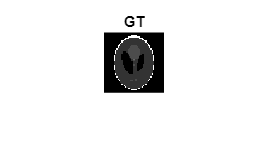

dimension=48;
GT=phantom("modified Shepp-Logan",dimension);

figure;
imshow(GT);
title("GT");

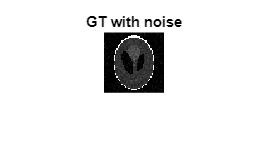


kspace=fftshift(fft2(GT));
repetition=50;

% Adding complex gaussian noise
GT_noise=add_gaussian_noise(GT,0.035,repetition);

figure;
imshow(squeeze(real(GT_noise(1,:,:))));
title("GT with noise");

% dim(X)=repetition*resolution
arranged_GT_noise=reshape(GT_noise,repetition,[]);

mean=sum(arranged_GT_noise,2)/dimension^2;
shifted_arranged_GT_noise=arranged_GT_noise-mean;

C=arranged_GT_noise*arranged_GT_noise'/(dimension^2);
[evector,evalue]=eig(C);


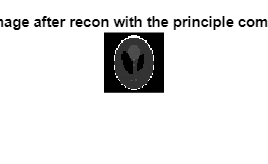

[~,index]=max(diag(evalue));
u_principal=evector(:,index);

temp=u_principal'*shifted_arranged_GT_noise;
recon=u_principal*temp;

figure;
recon=recon+mean;
recon1=squeeze(recon(1,:));
recon=reshape(recon1,dimension,dimension);
imshow(real(recon));
title("First image after recon with the principle component");


MSE=(sum((real(recon)-real(GT)).^2,"all")/(dimension^2))^(1/2);
disp(MSE);

    0.0049



MSE=(sum(((recon)-(GT)).^2,"all")/(dimension^2))^(1/2);
disp(MSE);

   0.0011 + 0.0014i



MSE=real((sum(((recon)-(GT)).^2,"all")/(dimension^2))^(1/2));
disp(MSE);

    0.0011



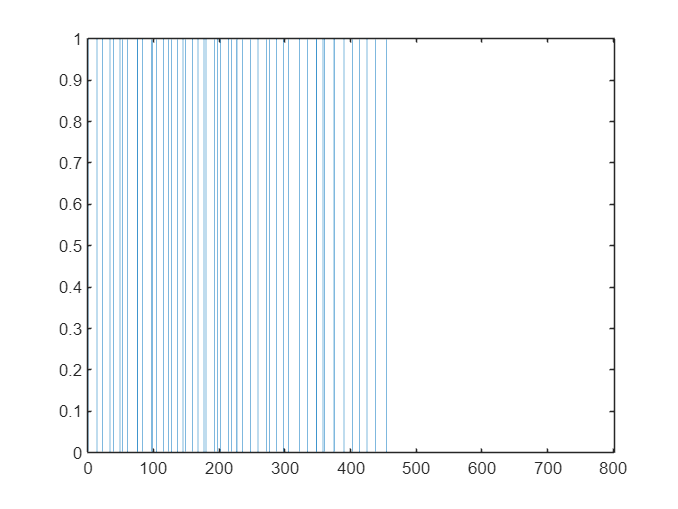

% Count

evalues=diag(evalue);

min_ev=min(evalues);
max_ev=max(evalues);
step=(max_ev-min_ev)/10e5;
count_ev=zeros(1,40);

for i=1:800
    if i==800
        count_ev(i)=sum((evalues>=((i-1)*step+min_ev))&(evalues<=(i*step+min_ev)));
    end
    count_ev(i)=sum((evalues>=((i-1)*step+min_ev))&(evalues<(i*step+min_ev)));
end
figure;
bar(count_ev);